% Create a simulator object
sim = Sim();


% Disable Radar initialization, since this example uses
% a single lane on the ground
sim.en_init_radar = false;
sim.en_init_atoc = false;

% Define a single-lane LBSD object
lane_length_m = 1000;
num_lanes = 1;
%lbsd = LBSD.genSimpleLanes(lane_length_m*ones(1,num_lanes));
lbsd = LBSD.genSampleLanes(lane_length_m, 1000);
sim.lbsd = lbsd;

% Initialize the uas configuration
uas_config = UASConfig();
uas_config.num_uas = 150;
% uas_config.setSpeedMix('CONSTANT',20)
uas_config.setSpeedMix('CONSTANT',10)
uas_config.setClimbRateMix('CONSTANT',10)
uas_config.setHeadwayMix('CONSTANT',350)
uas_config.setFlexMix('CONSTANT',100)

sim.uas_config = uas_config;

% initialize the simulation configuration
sim_config = SimConfig();
sim_config.t0 = 0;
sim_config.tf = 300;

sim.sim_config = sim_config;

figure;
% h_lbsd = lbsd.plot();
% disp(lbsd.lane_graph.Nodes)
% disp(lbsd.lane_graph.Edges)

sim.initialize(true);

Checking if LBSD is Instantiated
Initializing UAS Dataset
Initializing UAS Trajectories
Updating Metrics
Done


Simulation Started


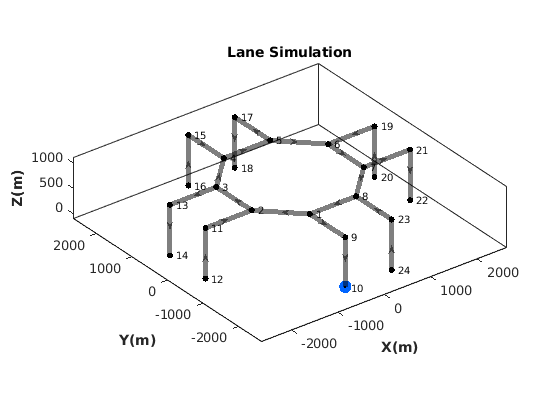

Simulation Complete


% sim.run_sim()

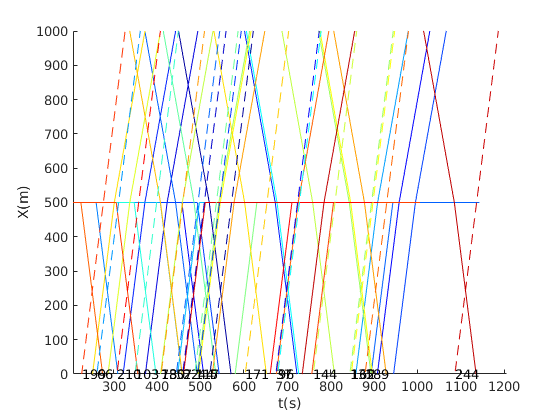

figure;
sim.plotTrajsX();

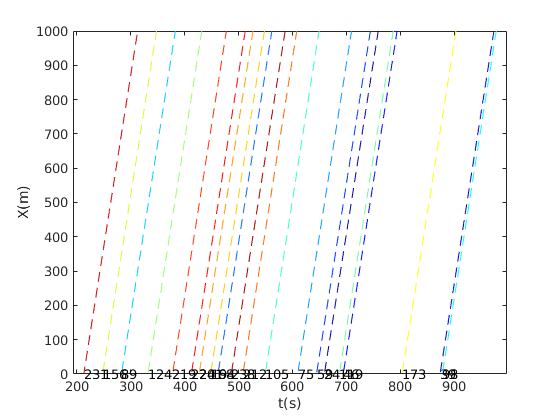

ans =   Line with properties:

              Color: [0 0 0.6000]
          LineStyle: '--'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×76600 double]
              YData: [1×76600 double]
              ZData: [1×0 double]

  Show all properties


sim.lbsd.plotLaneDiagram("3", false)

min_hd = sim.getMaxXDeviation();
disp(["Max Deviation from Planned Trajectory = " min_hd])

    "Max Deviation from Planned Trajectory = "    "13187.0886"



res = sim.lbsd.getReservations;
et = res.entry_time_s;
et = sort(et);
et_d = et(2:end)-et(1:end-1);
h_t = uas_config.hd_value/uas_config.speed_value;
all((et_d - h_t)>-100*eps)

ans = logical
   0


find((et_d - h_t)<-100*eps)

ans =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


sim.sim_metrics.lane_occs

ans = 1×24 struct array with fields:
    lane_id
    num_uas
    occ
